# Numerical example from "Virtual Reference Feedback Tuning (VRFT): a new direct approach to the design of feedback controllers", Campi et. Al.

The paper provides the plant transfer function:


$$P(z) = z^{-2} \frac{B(z)}{A(z)} = \frac{1 - 1.41833z^{-1} + 1.58939z^{-2} - 1.3106z^{-3} + .88642z^{-4}}{.28261z^{-1}+.50666z^{-2}}$$


The reference Model: 


$$M_R(z) = z^{-3} \frac{(1 - \alpha)^2}{(1 - \alpha  z^{-1})^2}$$


Where $\alpha = e^{-T_s\bar{\omega}}$ and $\bar{\omega} = 6$. Finally the controller class is: 


$$C(z;\theta) = \frac{\theta_0 + \theta_1z^{-1} + \theta_2z^{-2} + \theta_3z^{-3} + \theta_4z^{-4}}{1 - z^{-1}}$$


The sample time $T_s = 0.05s$ and the input/output data was obtained by passing 2000 samples of zero-mean Gaussian white noise through the plant model.

To start we express the information we have about the experiment

N = 2000;   % Number of samples
Ts = .05;  % Sample Time [s]

t_end = N*Ts - Ts;
t  = 0:Ts:t_end;   % Time vector

omega_bar = 6;

We can now build the plant model and use it to generate the input/output signals:

z = tf('z', Ts);

% Plant Model
B = (.28261 +  .50666 * z^-1);
A = (1 - 1.41833 * z^-1 + 1.58939 * z^-2 - 1.31608 * z^-3 + .88642 * z^-4);

Plant = z^-3 * B / A; 
Plant.Variable = 'z^-1'


Plant =
 
                0.2826 z^-3 + 0.5067 z^-4
  ------------------------------------------------------
  1 - 1.418 z^-1 + 1.589 z^-2 - 1.316 z^-3 + 0.8864 z^-4
 
Sample time: 0.05 seconds
Discrete-time transfer function.




% Input/Output signals
u = wgn(N, 1, 0);
y = lsim(Plant, u, t);

% Bode plot options for later
bodeopts = bodeoptions('cstprefs');
bodeopts.Grid = 'on';
bodeopts.PhaseVisible = 'off';

And the reference model:


alpha = exp(-Ts * omega_bar); 
RefModel = z^-3 * (1 - alpha)^2 / (1 - alpha * z^-1)^2;
RefModel.Variable = 'z^-1'


RefModel =
 
          0.06718 z^-3
  ----------------------------
  1 - 1.482 z^-1 + 0.5488 z^-2
 
Sample time: 0.05 seconds
Discrete-time transfer function.



We also build the controller vector:

% Controller family
c1 =    1 / (1 - z^-1);  c1.Variable = 'z^-1';
c2 = z^-1 / (1 - z^-1);  c2.Variable = 'z^-1';  
c3 = z^-2 / (1 - z^-1);  c3.Variable = 'z^-1';
c4 = z^-3 / (1 - z^-1);  c4.Variable = 'z^-1';
c5 = z^-4 / (1 - z^-1);  c5.Variable = 'z^-1';
c6 = z^-5 / (1 - z^-1);  c6.Variable = 'z^-1';
Controller = [c1 c2 c3 c4 c5 c6].';

% Controller Structure
% This code is only used to show that the controller has the right structure. 
ControllerFamily = Controller.' * ones(6, 1)


ControllerFamily =
 
  1 - 4 z^-1 + 6 z^-2 - 4 z^-3 + z^-4 - z^-6 + 4 z^-7 - 6 z^-8 + 4 z^-9 - z^-10
  -----------------------------------------------------------------------------
            1 - 6 z^-1 + 15 z^-2 - 20 z^-3 + 15 z^-4 - 6 z^-5 + z^-6
 
Sample time: 0.05 seconds
Discrete-time transfer function.



The controller above does not look like we would expect it to look but it is however correct. MATLAB is not intelligent enough to notice that all the terms of `Controller `have the same denominator and multiplies them together. Instead of:


$$\frac{\theta_0}{1 - z^{-1}} + \frac{\theta_1z^{-1}}{1 - z^{-1}}+ ...$$


MATLAB is basically calculating: 


$$\frac{\theta_0}{1 - z^{-1}} \frac{(1 - z^{-1})^5}{(1 - z^{-1})^5}+ \frac{\theta_1z^{-1}}{1 - z^{-1}} \frac{(1 - z^{-1})^5}{(1 - z^{-1})^5} + ...$$


to normalize all the denominators. To retrieve the original coeficients we need to use an identification method that we will detail further down.

Let's take a look at what we have so far:

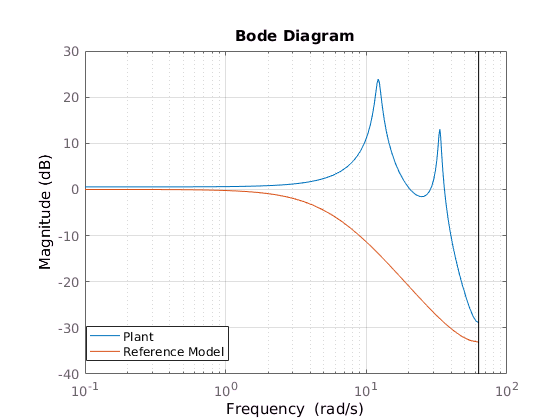

figure()
    bode(Plant, RefModel, bodeopts);
    legend('Plant', 'Reference Model', 'location', 'SouthWest');
    grid on;

We can now run the vrft tool on our data

[OptimalController, theta] = VRFT1_ry_theta(u, y, RefModel,  Controller, [], [], []);
OptimalController.Variable = 'z^-1'; 

Note: the tool is generating an optimal filter for us. If we do not want to use a filter then we need to set the last paratmeter to `1`. 

Since the controller is not in the same form as the controller from the paper we need to do some maths to calculate the values of the initial parameter vector:

Note: This is less useful now since I have found out how to extract the parameter vector from the output of vrft_engine but it is still interesting to compare the expected controller with the actual controller.

A = OptimalController.Numerator{:}; 
theta = zeros(1, 6); 

theta(1) = A(1); 
theta(2) = A(2) + 5 * theta(1); 
theta(3) = A(3) + 5 * theta(2) - 10 * theta(1);
theta(4) = A(4) + 5 * theta(3) - 10 * theta(2) + 10 * theta(1);
theta(5) = A(5) + 5 * theta(4) - 10 * theta(3) + 10 * theta(2) - 5 * theta(1);
theta(6) = A(6) + 5 * theta(5) - 10 * theta(4) + 10 * theta(3) - 5 * theta(2) + theta(1);

theta

theta =     0.1463   -0.2157    0.2462   -0.2064    0.1391   -0.0052

And calculate the loop transfer functions so we can evaluate the performance of our controller:

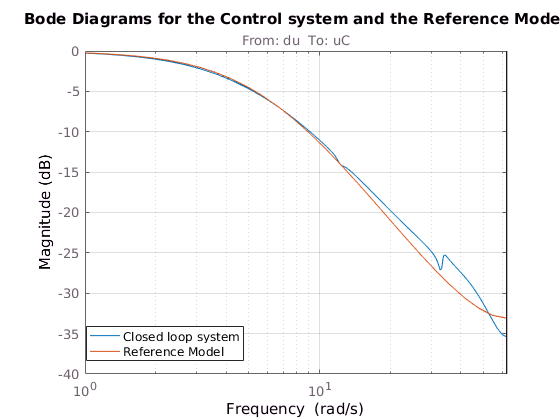

SensitivityFunctions = loopsens(Plant, OptimalController);

L_opt = SensitivityFunctions.Li;
S_opt = SensitivityFunctions.Si;
T_opt = SensitivityFunctions.Ti; 


figure()
    bode(T_opt, RefModel, bodeopts); 
    legend('Closed loop system', 'Reference Model', 'location', 'southWest');
    xlim([1 63]);
    title('Bode Diagrams for the Control system and the Reference Model');

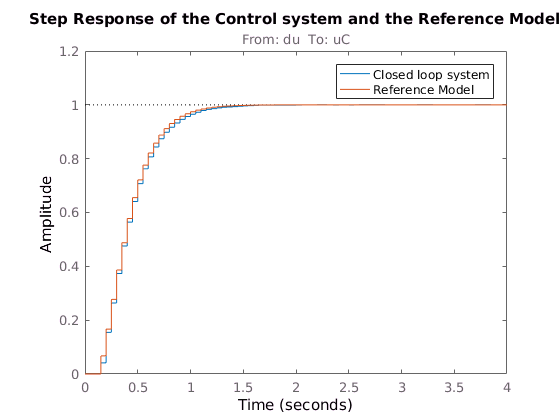

    
figure()
    step(T_opt, RefModel);
    title('Step Response of the Control system and the Reference Model');
    legend('Closed loop system', 'Reference Model');
    ylim([0 1.2]); xlim([0 4]);

Observer how close the step response of the reference model and the closed loop system are. We have a winner. 

## Something weird ...

Why does the closed loop system diverge like this after such a long time ? Is it a numerical problem or is there something more serious going on that I'm missing ?

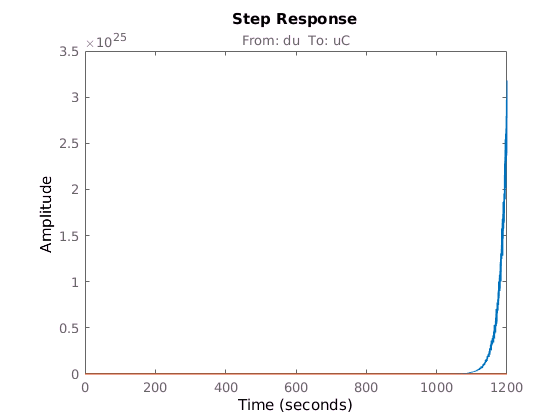

figure()
    step(T_opt, RefModel);